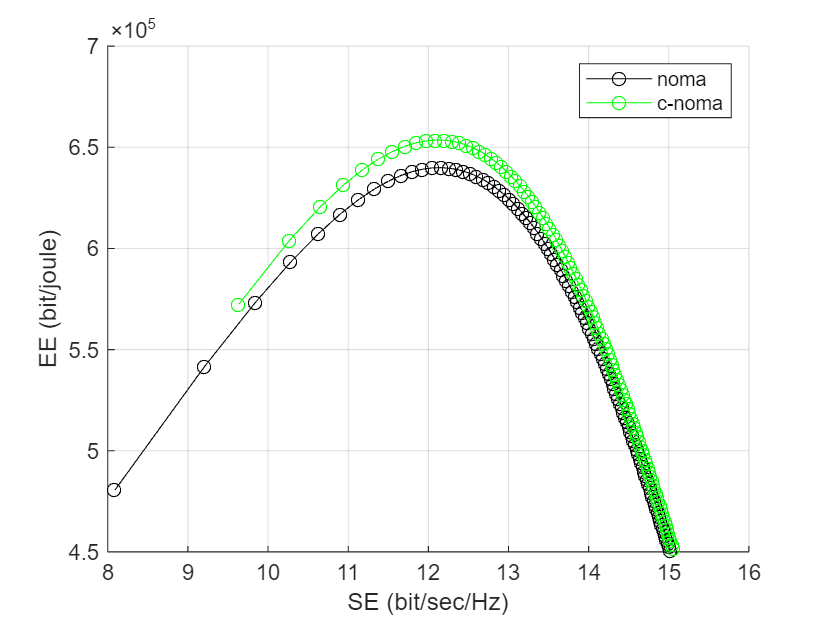

clc;
clear all;
B = 6*10^6; %bandwidth Hz
N0 = 10^-21; %-150 dBw/Hz
N = N0*B; % dBW
G1 = 10^-12; %-120 dB
G2 = 10^-14; %-140 dB
Pcircuit = 100; %watt
P3=50;
G3=10^-15;
%% NOMA
count = 1;
for p = 1:1:100 %W
R1 = B*log2(1 + p*G1/N);
R2 = B*log2(1 + p*G2/(p*G2 + N));
R = R1 + R2;
SE(count) = R/B; % bit/sec/Hz
EE(count) = (R/(Pcircuit + p)); % bit/watt.sec
count = count + 1;
end
hold on;
plot(SE,EE,'-ok');
xlabel('SE (bit/sec/Hz)');
ylabel('EE (bit/joule)');
grid on;
% C-Noma
count = 1;
for p = 1:1:100 %W
R1 = B*log2(1 + p*G1/N);
R2 = B*log2(1 + p*G2/(p*G2 + N)+P3*G3/(p*G2+N));
R = R1 + R2;
SE_line(count) = R/B; % bit/sec/Hz
EE_line(count) = (R/(Pcircuit + p)); % bit/watt.sec = Mbit/joule
count = count + 1;
end
hold on;
plot(SE_line,EE_line,'-og');
legend('noma','c-noma')